# Inverters

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Power inverters are electronic devices designed to convert direct current (DC) into alternating current (AC). To convert DC to AC with an inverter, a controllable switch/gate is required. They play a crucial role in various applications including solar panel systems, portable power supplies, and electric vehicles (EVs), where they convert the DC electricity from batteries into AC electricity to drive electric motors. In this script, we will explore the theory and applications of inverters in power electronics.

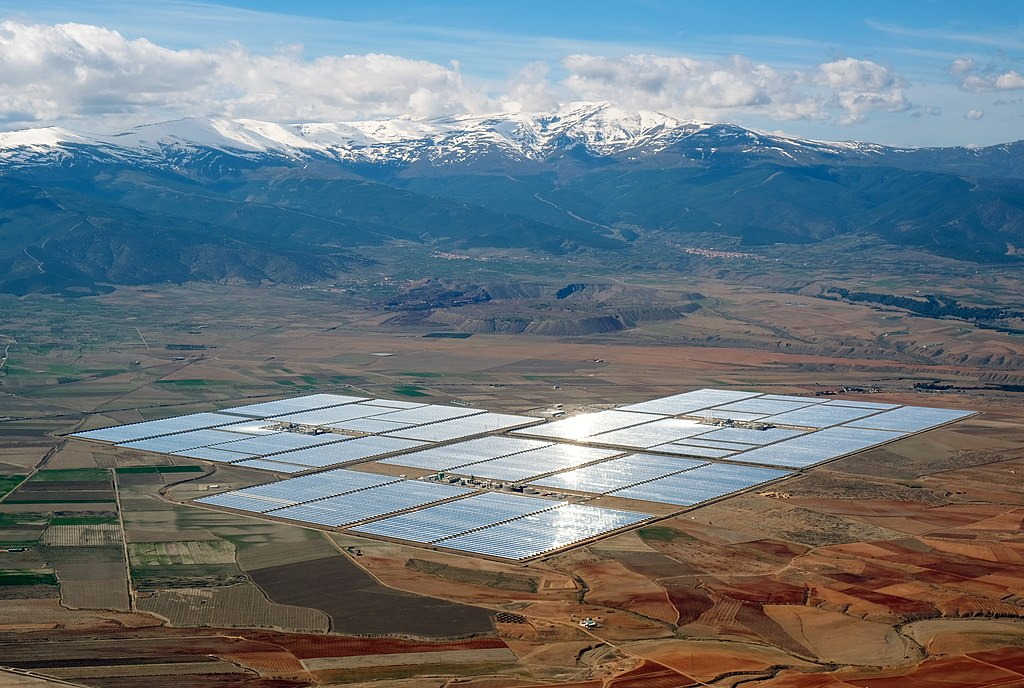

Andasol Solar Power Station from [Wikipedia Commons](https://commons.wikimedia.org/wiki/File:Andasol_Guadix_4.jpg) - [CC BY-SA 4.0](https://creativecommons.org/licenses/by-sa/4.0/deed.en)

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Switch control with pulse width modulation

The conversion of DC to AC power in inverters is all done through a series of switches driven by pulse width modulation (PWM). Based on how the PWM is structured, two switches will capture the positive waveform and the other two switches will capture the negative waveform, creating a complete AC signal. PWMs are characterized by having a switching frequency of 10 kHz. The input to each switch driven by PWM is a duty cycle ranging from 0 to 1. There are a couple of different ways to model a PWM signal. One way to accomplish this is by comparing a [sawtooth](https://www.mathworks.com/help/releases/R2024a/signal/ref/sawtooth.html?overload=sawtooth+false) signal to a provided duty cycle input. When the duty cycle value is greater than the duty cycle, the PWM output is 1 (switch on). When the duty cycle is less than the sawtooth value, the PWM output is 0 (switch off). In programming languages, the output of the comparison between a scalar value (duty cycle) and a sawtooth signal produces a [`logical`](https://www.mathworks.com/help/matlab/ref/logical.html) value. This requires a data type conversion to a [`double`](https://www.mathworks.com/help/matlab/ref/double.html?searchHighlight=double&s_tid=srchtitle_support_results_1_double) for use as an input to a switch. The other way is to utilize a [PWM generator](https://www.mathworks.com/help/releases/R2024a/sps/ref/pwmgenerator.html) which does not require a comparison or data type conversion. For the models used later in this script, we will be using the latter approach. You can view the two approaches using the following dropdown menu:

switchApproach("No Selection");

## Types of inverters

The majority of our household appliances operate on AC power, supplied by a variety of power sources (traditional/renewable) from the electrical grid. When discussing renewable sources, namely solar panels, the output of these devices supplies electricity in the form of DC power. This means an inverter is required to convert the DC power into AC power to use within our households. There are three types of inverters: square wave, modified sine wave, and pure sine wave. Each type of inverter is described further in the table below:

 **Exercise 1. **Which of the following statements are true regarding pure sine wave inverters? Please select all that apply and click the **Submit Answers** button below.  

exerciseSol1(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);

### Square wave 

Square wave inverters are generally not used at all nowadays in most applications but could be used if you are powering simple tools. These types of inverters have sharp changes between high and low states which would make it hard for a normal device to operate without resulting in damage to the tool. Because of their simplicity, they are less expensive to manufacture because of minimal components and thus easier to repair and maintain. One benefit of this type of inverter is that it is able to handle more significant power spikes compared to the more complex inverters like pure sine wave inverters. 

** Demonstration**. Let's simulate a simple square wave inverter to visualize the circuit's behavior. Observe that we are starting with a 5V DC signal, and by means of PWM switching, we will achieve a square wave AC signal as the output.

% View square wave signal
sqwFlag = false;

% Run the Simscape model for the square wave inverter and store data from
% simulation
if sqwFlag
    SQWaveData = sim("Models/SquareWaveInverter.slx","StopTime","0.001"); %#ok<UNRCH>

    % Plot square wave inverter output voltage signal
    t1 = SQWaveData.ScopeData(:,1);
    v1 = SQWaveData.ScopeData(:,2);
    v1(:,1) = 5;
    t2 = SQWaveData.ScopeData(:,1);
    v2 = SQWaveData.ScopeData(:,2);
    plot(t1,v1,':',t2,v2,'-','LineWidth',2);
    ylim([-8 8]);
    xlabel('Time (sec)'); ylabel('Voltage (V)');
    title('Square Wave Inverter Output Voltage');
    legend("Original DC Signal","Inverted AC Signal");
end

  **Try**. Explore a **square wave inverter** in Simscape that created the response. In this model, the load is only characterized by a resistor which will yield a square wave based on the controlling input signal. You can simulate the model using the run icon  .

 

% Open Simscape model for the square wave inverter
open_system("Models/SquareWaveInverter.slx")

### Modified sine wave

Modified sine wave inverters are used in many standard applications today because of their broad range of compatibility. It is a more cost-effective alternative to pure sine wave inverters because it produces a stepped waveform that approximates the shape of a pure sine wave. This reduces the amount and quality of components and, thus, the cost of manufacture. The stepped nature of modified sine wave signals generates more heat in the electronics, reducing the lifespan of devices. The major benefit of this type of inverter is being a good balance between performance, efficiency, and cost for many household and industrial needs.

** Demonstration**. Let's simulate a simple modified sine wave inverter to visualize the circuit's behavior. Observe that we are starting with a 5V DC signal, and by means of PWM switching, we will achieve a modified sine wave AC signal as the output.

% View modified sine wave signal
mswFlag = false;

% Run the Simscape model for the modified sine wave inverter and store data from
% simulation
if mswFlag
    ModSinWaveData = sim("Models/ModSineWaveInverter.slx","StopTime","0.1"); %#ok<UNRCH>

    % Plot modified sine wave inverter output voltage signal
    t1 = ModSinWaveData.ScopeData(:,1);
    v1 = ModSinWaveData.ScopeData(:,2);
    v1(:,1) = 5;
    t2 = ModSinWaveData.ScopeData(:,1);
    v2 = ModSinWaveData.ScopeData(:,2);
    plot(t1,v1,':',t2,v2,'-','LineWidth',2);
    ylim([-8 8]);
    xlabel('Time (sec)'); ylabel('Voltage (V)');
    title('Modified Sine Wave Inverter Output Voltage');
    legend("Original DC Signal","Inverted AC Signal");
end

  **Try**. Explore a **modified sine wave inverter** in Simscape that created the response. In this model, you will notice the addition of a capacitor and an inductor to the load. This helps reduce voltage ripple and smooth the signal. The controlling input signal is still a square wave.

 

% Open Simscape model for the modified sine wave inverter
open_system("Models/ModSineWaveInverter.slx")          

### Pure sine wave

Pure sine wave inverters are the most versatile and most expensive to manufacture. This type of inverter produces the highest quality (clean and stable) AC power, which is critical for sensitive electronic devices and equipment that can be affected by electrical noise, such as devices in the medical industry. One benefit of this type of inverter is that because the signal is smoother, it produces less electrical noise compared to other inverters. The pure sine wave inverter operates more efficiently with less heat generation as compared to the modified sine wave inverter. This quality helps to extend the lifespan of the equipment and improve performance.

** Demonstration**. Let's simulate a simple pure sine wave inverter to visualize the behavior of the circuit. Observe that we are starting with a 5V DC signal and by means of PWM switching, we will achieve a pure sine wave AC signal as the output. You will notice some ripples in the sine wave output. That is because it is very difficult to achieve a fully smooth sine wave without requiring more components and thus incurring more costs.

% View pure sine wave signal
pswFlag = false;

% Run the Simscape model for the pure sine wave inverter and store data from
% simulation
if pswFlag
    PureSinWaveData = sim("Models/PureSineWaveInverter.slx","StopTime","0.1"); %#ok<UNRCH>

    % Plot pure sine wave inverter output voltage signal
    t1 = PureSinWaveData.ScopeData(:,1);
    v1 = PureSinWaveData.ScopeData(:,2);
    v1(:,1) = 5;
    t2 = PureSinWaveData.ScopeData(:,1);
    v2 = PureSinWaveData.ScopeData(:,2);
    plot(t1,v1,':',t2,v2,'-','LineWidth',2);
    ylim([-8 8]);
    xlabel('Time (sec)'); ylabel('Voltage (V)');
    title('Pure Sine Wave Inverter Output Voltage');
    legend("Original DC Signal","Inverted AC Signal");
end

  **Try**. Explore a **pure sine wave inverter** in Simscape that created the response. In this model, the capacitor and inductor are still present. The controlling input signal has now been changed to a sine wave.

 


% Open Simscape model for the pure sine wave inverter
open_system("Models/PureSineWaveInverter.slx") 

 **Reflect. **If you look closely, there is a noticeable ripple in the signal. This is due to the sizing of the capacitor. Remember, adding a capacitor to a circuit helps to reduce voltage ripple. What happens if you remove the capacitor and rerun the simulation?

### Analyzing solar power conversion

You are an architect designing a house that is powered solely by renewable energy. When it comes to renewable energy, solar power is one of the primary ways that residential households use to reduce their carbon footprint and have more control over how their electricity is used. During the conversion of solar power to electricity, you will have some losses in the form of heat. Your output from the solar panel will be a smooth DC voltage signal. As you may recall, the appliances in your household operate primarily on AC power. Therefore, an inverter must be a part of a renewable energy solution for your home. In this example, we will explore a **pure sine wave inverter** within a solar power generation application.

In photovoltaic (PV) systems, an algorithmic technique known as [maximum power point tracking (MPPT)](https://www.mathworks.com/discovery/mppt-algorithm.html#:~:text=Maximum%20power%20point%20tracking%20(MPPT,changing%20solar%20irradiance%2C%20temperature%2C%20and) is used to maximize energy extraction of the solar panel as conditions vary. The algorithm works by iterating on known inputs over a period of time to determine a specific output. From a hardware perspective, the inputs are measured from the solar panels and fed to the MPPT algorithm. The algorithm then produces an output that is supplied to a [buck-boost converter](matlab:open('./Converters.mlx')). The buck-boost converter will either step up or step down voltage. This is because a solar panel will generate different voltage levels as the intensity of the sun changes throughout the day. Therefore, the buck-boost converter helps to achieve maximum power at any point in the day. That voltage is then provided to an inverter, battery, or both, depending on the system. 

Your task will be utilizing this technique to maximize the amount of power extracted from a couple of solar panels on a given day. The specific algorithm we will focus on for this problem will be perturb and observe (P&O), where small incremental changes are made to the output.

 **Exercise 2. **What are the inputs required to perform MPPT with P&O? For an overview of P&O, review the MPPT link above. Once you have made your selection, click the **Submit Answers** button below. 

exerciseSol2("No Selection");

 **Exercise 3.** Complete the following P&O algorithm for MPPT below. This programmatic code represents a single iteration for determining the duty cycle based on an input voltage and current. As a reminder, you can view the P&O flow chart [here](https://www.mathworks.com/discovery/mppt-algorithm.html#:~:text=Maximum%20power%20point%20tracking%20(MPPT,changing%20solar%20irradiance%2C%20temperature%2C%20and) to understand how to write the logic behind the MPPT algorithm. Use the drop-down menu below the algorithm **to view and select the correct code fragment (**`###`**) that is missing.** Once you have **reviewed** your selection, click the **Submit Answers** button below. 

selection = switchFragment("No Selection");

 
exerciseSol3(selection);

 **Note. **Adding a [`for`](https://www.mathworks.com/help/matlab/ref/for.html?searchHighlight=for&s_tid=srchtitle_support_results_1_for) loop to this algorithm would allow you to cycle through a series of inputs with the result of a series of outputs or duty cycles. Through this method, you would be able to continuously maximize power for a solar panel at any point in the day.

 **Exercise 4.** Open the solar power inverter model. This model contains an MPPT algorithm, an inverter, and a solar panel component. Explore the model and learn all the systems components. 


 

% Open Simscape model for the solar power inverter model
open_system("Models/SolarPowerInverterModel.slx")

Before simulation, set the initial duty cycle percentage knob in the model to 75% (0.75). **Estimate** the maximum power that can be acheived with this panel at a given irradiance of 1000 W/m^2 and a panel output voltage of 25 VDC. You can simulate the model using the run icon   in the model toolstrip. Utilize the Power vs. Voltage figure that appears post-simulation to determine the max power.


maxPower = 0; % Maximum Power (W)
exerciseSol4(maxPower);

 **Exercise 5. **Given the initial MPPT duty cycle of 75% provided in the previous exercise, **estimate** the final output voltage from the solar panel at the last tracked point of maximum power? Hint: Follow the green circle.

finalV = 0; % Output Voltage (V)
exerciseSol5(finalV);

 **Note.** The scope block is used to display specific parameters chosen by the user. What if you want to view **all** of the parameters across blocks in a model? The Simulink Data Inspector   tool allows you to view all of your parameters in one place. Once a simulation is run, a `simlog `variable will appear in the workspace. Click the data inspector icon and select the import data button . Select the import button, and you will be able to view all the signals and parameters in the model.

## Next Steps

This script covered the fundamentals of three types of inverters in power electronics: square wave, modified sine wave, and pure sine wave. In later sections of this power electronics module, we will explore other related topics on rectifers and converters.

## Glossary

Pulse Width Modulation -  Any method of representing a control signal as a rectangular wave with varying duty cycle or load. (↑ Return to Text)

Duty Cycle - The ratio of time (pulse) a load or circuit is on compared to the time it is off. (↑ Return to Text)

## Further Exploration

- [Power Electronics Simulation in MATLAB](https://www.mathworks.com/solutions/electrification/power-electronics-simulation.html)

- [Power Electronics Simulation Onramp](https://matlabacademy.mathworks.com/details/power-electronics-simulation-onramp/powerelectronics)

- [MathWorks Examples: Power Converters](https://www.mathworks.com/help/sps/examples.html?category=power-converters&s_tid=CRUX_topnav)

- [MathWorks: Introduction to Power Inverters](https://www.mathworks.com/videos/what-is-3-phase-power-part-6-introduction-to-power-inverters-1655100703794.html)

- [Power Electronics with Speedgoat for RCP & HIL](https://www.speedgoat.com/solutions/industries/power-electronics?utm_term=power%20electronics%20matlab&utm_source=google&utm_medium=cpc&device=c&utm_campaign=10278398312&utm_adgroup=135515401899&utm_content=591792460255&gad_source=1&gclid=EAIaIQobChMIy5nB66CEhAMVXl9HAR2KgQSMEAAYASAAEgK42_D_BwE)

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function switchApproach(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Sawtooth" "PWM"])}
end

if opt == "No Selection"
else
    if opt == "Sawtooth"
        rect = imread("Images/Sawtooth.png");
        imshow(rect,Interpolation="bilinear");
    elseif opt == "PWM"
        rect = imread("Images/PWM.png");
        imshow(rect,Interpolation="bilinear");
    end
end
end

function exerciseSol1(opts)
    % Provides solution for Exercise 1
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select all that apply!")
    elseif [opts.A opts.B opts.C opts.D] %#ok<BDSCA>
        disp("Correct! These are all true statements of a pure sine wave inverter.")
    elseif [opts.A opts.B] & ~[opts.C opts.D] | [opts.A opts.C] & ~[opts.B opts.D] | [opts.A opts.D] & ~[opts.B opts.C] | [opts.B opts.D] & ~[opts.A opts.C] | [opts.C opts.D] & ~[opts.A opts.B] | [opts.B opts.C] & ~[opts.A opts.D]  %#ok<AND2,OR2,BDSCA>
        warning("Incorrect. You have not selected all the true statements about a pure sine wave inverter.");
    elseif opts.A
        warning("Yes, pure sine wave inverters are the most expensive to manufacture. This is not the only feature of pure sine wave inverter.")
    elseif opts.B
        warning("Yes, pure sine wave inverters output sine waves that are similar to a typical input to AC machinery. This is not the only feature of pure sine wave inverter.")
    elseif opts.C
        warning("Yes, it is very difficult and expensive to recreate a perfect sine wave with a pure sine wave inverter. This is not the only feature of pure sine wave inverter.")
    elseif opts.D
        warning("Yes, pure sine wave inverters can be used to power almost any appliance. This is not the only feature of pure sine wave inverter.")
    end
end

function exerciseSol2(subs)
    % Provides solution for Exercise 2
    arguments
        subs (1,1) string {mustBeMember(subs,["No Selection" "Voltage and Current" "Voltage and Irradiance" "Resistance and Power" "Current and Duty Cycle"])} = "No Selection"
    end

    switch (subs)
        case "No Selection"
            disp("Please select one of the options in the drop down menu.")
        case "Voltage and Current"
            disp("Correct! Both voltage and current are inputs to perform MPPT. By utilizing these inputs, the algoritm produces an output in the form of a duty cycle.")
        case "Voltage and Irradiance"
            warning("Incorrect. Irradiance is an input directly for a solar panel regarding how much radiant flux is received by a surface area.")
        case "Resistance and Power"
            warning("Incorrect. Resistance is not a variable that changes with time.")
        case "Current and Duty Cycle"
            warning("Incorrect. Duty cycle is an output from an MPPT algorithm.")
    end
end

function idx = switchFragment(img)
    % Switches between different code snippets for Exercise 3
    arguments
        img (1,1) string {mustBeMember(img,["No Selection" "Fragment 1" "Fragment 2" "Fragment 3" "Fragment 4"])}
    end
    
    if img == "No Selection"
        idx = 0;
    else
        if img == "Fragment 1"
            code = imread("Images/POIncorrect1.png");
            imshow(code,Interpolation="bilinear");
            idx = 1;
        elseif img == "Fragment 2"
            code = imread("Images/POIncorrect2.png");
            imshow(code,Interpolation="bilinear");
            idx = 2;
        elseif img == "Fragment 3"
            code = imread("Images/POIncorrect3.png");
            imshow(code,Interpolation="bilinear");
            idx = 3;
        elseif img == "Fragment 4"
            code = imread("Images/POCorrect.png");
            imshow(code,Interpolation="bilinear");
            idx = 4;
        end
    end
end


function exerciseSol3(frag)
    % Provides solution for Exercise 3
    
    if frag == 0
    else
        if frag == 1
            warning('Incorrect. Pay attention to the operand signs when working through the P&O logical flow diagram.')
        elseif frag == 2
            warning('Incorrect. Pay attention to the comments about what is happening to the duty cycle/voltage reference and compare it to the logical flow diagram.')
        elseif frag == 3
            warning('Incorrect. Pay attention to the mathematical operations being used for the duty cycle equations.')
        elseif frag == 4
            disp('Correct! This code fragment represents the proper logical flow for a P&O MPPT algorithm.')
        end
    end
end

function exerciseSol4(power)
    % Provides solution for Exercise 4
    arguments
        power (1,1) double
    end

    if power >= (251.505) && power <= (254.83)
        disp("Correct! You have properly calculated the maximum power of the solar cell system.")
    elseif power == 0
        disp("Please enter your answer.")
    else
        warning("Your answer has exceeded the tolerance of the possible solutions. Please measure the maximum power of the solar cell system again.")
    end
end

function exerciseSol5(voltage)
    % Provides solution for Exercise 5
    arguments
        voltage  (1,1) double
    end

    if voltage >= (31.79 - 1.5) && voltage <= (31.79 + 1.5)
        disp("Correct! You have properly determined the output voltage of the solar panel at the final point of maximum power.")
    elseif voltage == 0
        disp("Please enter your answer.")
    else
        warning("Your answer has exceeded the tolerance of the possible solutions. Please measure the output voltage at the final point of maximum power again.")
    end
end